## Add MLIB library

clear; close all; clc;
%mlibfolder = '/remote/data/ivan/share/MLIB';
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;




G = GridClass; 
G.x0 = -2500; 
G.dx = 5;
G.nx = 1001;
G.z0 = 0;
G.dz = 5;
G.nz = 401;
G.t0 = 0;
G.dt = 0.002;
G.nt = 15001;

G.setGrid


fc = 30;               % dominant frequency of the signal
damp  = 40;            % attenuation factor (for signal modeling)
sigma = 0.05;          % variance of noise is equal sigma^2
tau = 0.30;            % onset of the signal

Non-symmetric signal:


$$s\left(t\right)=h\left(t\right)\cdot \;\mathrm{sin}\left(2\pi \;f_{c\;} \left(t-\tau \;\right)\right)e^{-A\left|t-\tau \right|}$$


get_nsm_signal  = @(t,tau,fc,damp)(   myheaviside(t-tau).*sin(2*pi*fc*(t-tau)).*exp(-damp*(t-tau))   );

Noise:

get_noise = @(t,sigma)(   sigma*randn(size(t))   );

Create noisy signal

signal = get_nsm_signal(G.tt, tau, fc, damp)

signal =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


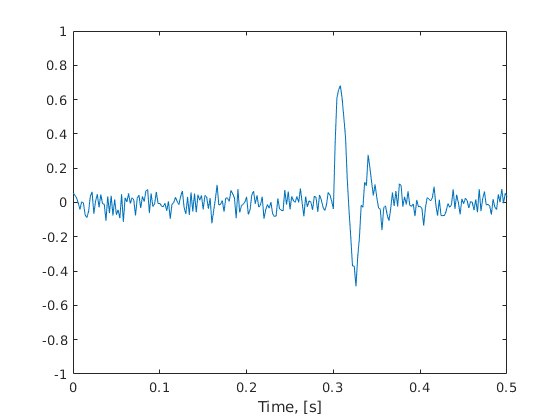

noise = get_noise(G.tt,sigma);

noisy_signal = signal + noise; 
figure(1)
plot(G.tt, noisy_signal)
axis([0 0.5 -1 1])
xlabel('Time, [s]')

velmod = 3000*ones(G.nx, G.nz);


calculate traveltimes

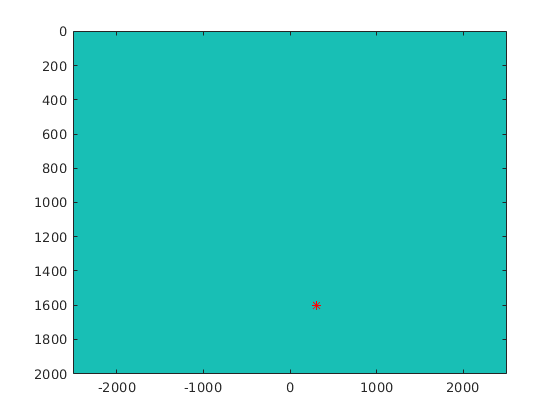



tti = zeros(G.nx, G.nz);

xs = 300;
zs = 1600; 

figure(2)
imagesc(G.xx, G.zz, velmod')
hold on
plot(xs, zs, 'r*')



tic
for i=1:G.nx
    for j = 1:G.nz
        xr = G.xx(i);
        zr = G.zz(j);
        dist = sqrt((xs - xr)^2 + (zs - zr)^2);
        tti(i,j) = dist/3000;
    end
end
toc

Elapsed time is 2.658102 seconds.



[XX, ZZ] = meshgrid(G.xx, G.zz);
tic
ttiv = sqrt((XX - xs).^2 + (ZZ - zs).^2)/3000;
toc

Elapsed time is 0.004165 seconds.


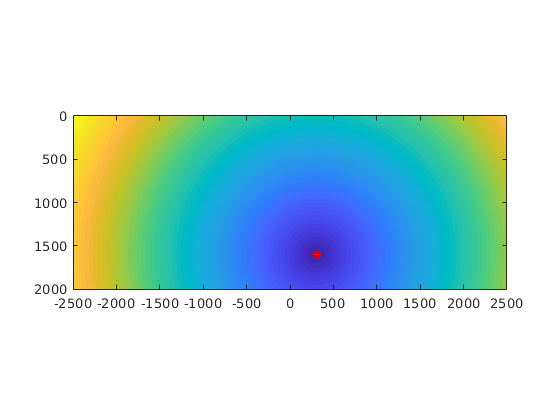


%Vs = v0 + k*xs(3);                                   % velocity at the source point 
%Vr = v0 + k*ZZ;                                      % velocity at the point on reflector
%R = (xs(1)-XX).^2+(xs(3)-ZZ).^2;                       % distance from the source to the reflector point
%t = 1/k*acosh(1 + k^2*R./(2*Vs*Vr));               % traveltime in the medium with linear gradient of velocity 



figure(3)
imagesc(G.xx, G.zz, tti')
hold on
plot(xs, zs, 'r*')
axis equal
axis([G.x0 G.mx G.z0, G.mz])

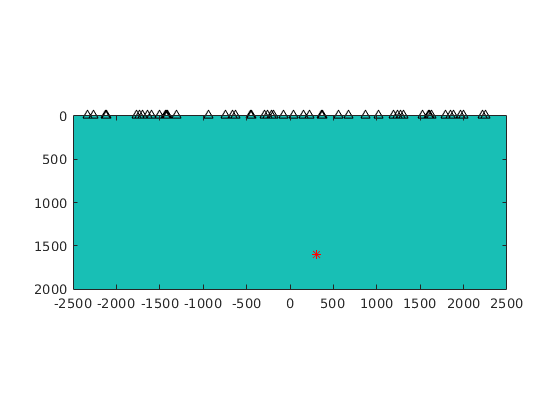


%acq.xr = [-2500 -2000 -1500 -1000 -500 -000 500 1000 1500 2000 ];
%acq.zr = [ 0     0      0      0    0    0      0    0      0     0   ];

acq.xr = rand(50,1)*5000-2500; 
acq.zr = zeros(size(acq.xr));


nrece = length(acq.xr);

figure(4)
imagesc(G.xx, G.zz, velmod')
hold on
plot(acq.xr, acq.zr, 'k^')
plot(xs, zs, 'r*')
axis equal
axis([G.x0 G.mx G.z0, G.mz])

simulate synthetic data

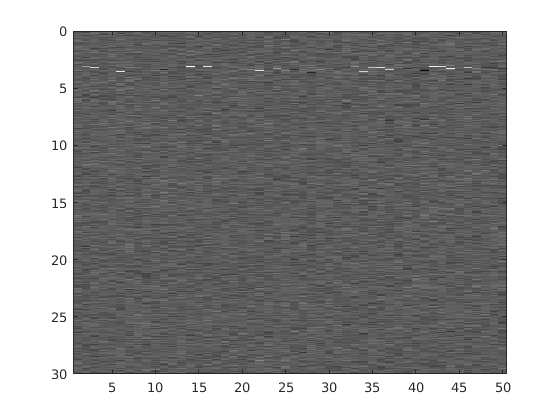

te = 2.57;  % excitation time

tr = sqrt((acq.xr - xs).^2 + (acq.zr - zs).^2)/3000; 

tau = te + tr; 

% generate synthetic data


data = zeros(G.nt, nrece);

for r = 1:nrece
    signal = get_nsm_signal(G.tt, tau(r), fc, damp);
    noise = get_noise(G.tt,sigma);
    noisy_signal = signal + noise; 
    data(:,r) = noisy_signal;
end

% plot the data

figure(6)
imagesc(1:nrece, G.tt, data)
colormap('gray')

## Compute traveltimes

TTI = zeros(G.nx,G.nz,nrece);

for r=1:nrece
    tti = sqrt((XX - acq.xr(r)).^2 + (ZZ - acq.zr(r)).^2)/3000;
    TTI(:,:,r) = tti'; 
end

## Compute DS image

ttzero = 2:0.01:3.0;        
J = zeros(G.nx,G.nz,length(ttzero));

for k=1:length(ttzero)

    tzero = ttzero(k);
    I = zeros(G.nx,G.nz);
    
    for r=1:nrece
        trace = data(:,r);   
        
        trace = trace; % 1 
        %trace = trace.^2; % 2
        %trace = abs(hilbert(trace)); % 3 envelopes
        
        tti = TTI(:,:,r); 
        ntp=round((tzero+tti)/G.dt);
        ntp=min(max(ntp,1),G.nt); 
        I = I + trace(ntp);
    end
    J(:,:,k) = I; 
    disp(k) 
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101



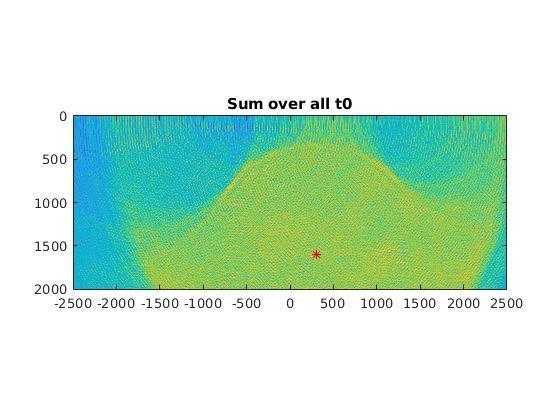


% 1 stack all possible t0
figure(19)
sJ = sum(J,3); % a sum over all t0
imagesc(G.xx, G.zz, sJ');
hold on 
plot(xs, zs, 'r*')
title('Sum over all t0')
axis equal
axis([G.x0 G.mx G.z0, G.mz])

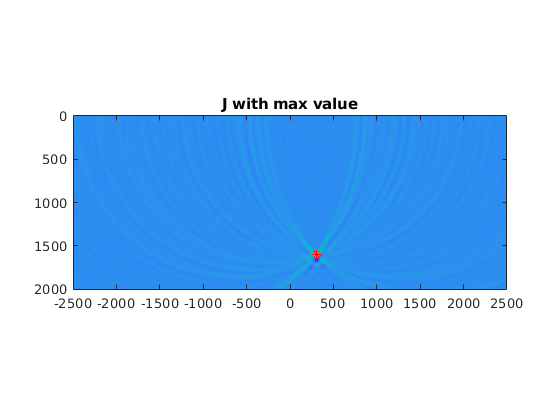


% 2 find the maximum of J 
figure(110)
[maxpdf, maxind] = max(J(:));
[maxi,maxk,maxt] = ind2sub(size(J),maxind);
mJ = J(:,:,maxt);
imagesc(G.xx, G.zz, mJ');
hold on 
plot(xs, zs, 'r*')
title('J with max value')
axis equal
axis([G.x0 G.mx G.z0, G.mz])